clear; close all;


AnimalFolder = uigetdir("F:\YuLab\Work\GPS\Data\");
if ~AnimalFolder
    return;
end
[~, Animal] = fileparts(AnimalFolder);

FigFolder = fullfile(AnimalFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end

TaskFolders = get_folders(AnimalFolder, "FolderType", "Protocol");
TaskTiming = [
    "Kornblum1000SRTSelf";
    "Kornblum1500SRTSelf";
    "Kornblum2000SRTSelf";
    ];

[Parents, Tasks] = arrayfun(@(x) fileparts(x), TaskFolders);
TimingInd = contains(Tasks, TaskTiming);
TaskFolders = TaskFolders(TimingInd);
Parents = Parents(TimingInd);
Tasks = Tasks(TimingInd);

[indx, tf] = listdlg("ListString", Tasks, "ListSize", [200, 200]);
if ~tf
    return
end

TaskFolders = TaskFolders(indx);

NumTasks = length(TaskFolders);
BehClass = cell(NumTasks, 1);
FPs = zeros(NumTasks, 1);
for i = 1:NumTasks
    ProgressClassPath = get_mat_files(TaskFolders(i), "FileType", "ProgressClass");
    if length(ProgressClassPath)>1
        fprintf("more than one ProgressClass");
        return;
    end
    load(ProgressClassPath);
    BehClass{i} = obj;
    FPs(i) = obj.TargetFP;
end
clear obj;

Ports = ["L", "R"];


HD.Control = cell(3,2); HD.Chemo = cell(3,2);
RT.Control = cell(3,2); RT.Chemo = cell(3,2);
MT.Control = cell(3,2); MT.Chemo = cell(3,2);
HDPDF.Control = cell(3,2); HDPDF.Chemo = cell(3,2);
HDCDF.Control = cell(3,2); HDCDF.Chemo = cell(3,2);
LogSTPDF.Control = cell(3,3); LogSTPDF.Chemo = cell(3,3);

for fp = 1:3
    HD.Control(fp,:) = BehClass{fp}.HDSorted.Control(2,:);
    HD.Chemo(fp,:) = BehClass{fp}.HDSorted.Chemo(2,:);

    RT.Control(fp,:) = BehClass{fp}.RTSorted.Control(2,:);
    RT.Chemo(fp,:) = BehClass{fp}.RTSorted.Chemo(2,:);

    MT.Control(fp,:) = BehClass{fp}.MTSorted.Control(2,:);
    MT.Chemo(fp,:) = BehClass{fp}.MTSorted.Chemo(2,:);

    HDPDF.Control(fp,:) = BehClass{fp}.HDPDF.Control(2,:);
    HDPDF.Chemo(fp,:) = BehClass{fp}.HDPDF.Chemo(2,:);

    HDCDF.Control(fp,:) = BehClass{fp}.HDCDF.Control(2,:);
    HDCDF.Chemo(fp,:) = BehClass{fp}.HDCDF.Chemo(2,:);

    LogSTPDF.Control(fp,:) = BehClass{fp}.LogSTPDF.Control(2,:);
    LogSTPDF.Chemo(fp,:) = BehClass{fp}.LogSTPDF.Chemo(2,:);
end

## Hold duration and reaction time

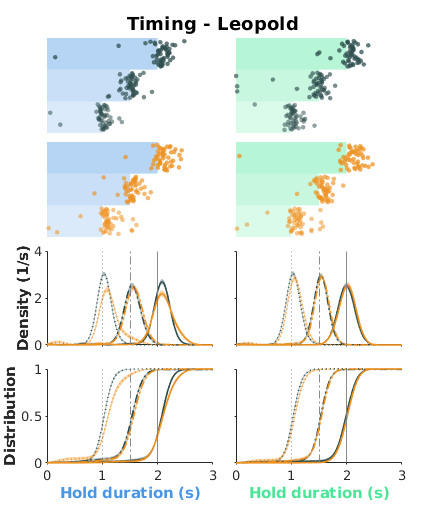

fig_hd = figure(31); clf(fig_hd);
set(fig_hd, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 9 11], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_hd, sprintf("Timing - %s", Animal), 'FontSize', 11);

% show trials
DrawTrials(fig_hd, [1 6 7.5 6.4], [3.5 2], HD);

% plot PDFs and CDFs
DrawDistr(fig_hd, [1 1.2 7.5 4.5], [3.5 2], HDPDF, HDCDF);

fig_name = sprintf("Test_Timing_HD_Chemo_%s", Animal);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_hd, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_hd, fig_path+".pdf", 'ContentType', 'vector');

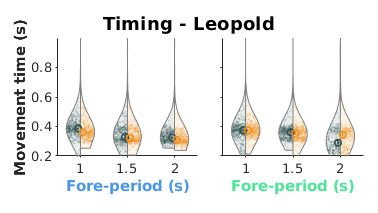

fig_movement = figure(33); clf(fig_movement);
set(fig_movement, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 4.5], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_movement, sprintf("Timing - %s", Animal), 'FontSize', 11);

ax_mt = DrawViolin(fig_movement, [1.2 1.2 6.5 5.5], [3 2.5], FPs, MT, 1);
for i=1:numel(ax_mt)
    ax_mt{i}.YLim=[0.2 1];
end
ylabel(ax_mt{1}, "Movement time (s)", 'FontWeight', 'bold');

fig_name = sprintf("Test_Timing_Movement_Timing_Chemo_%s", Animal);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_movement, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_movement, fig_path+".pdf", 'ContentType', 'vector');

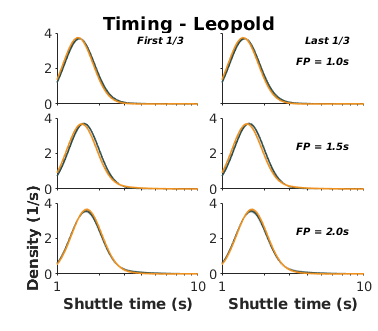

fig_st = figure(34); clf(fig_st);
set(fig_st, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 8 7], 'Color', 'w', 'toolbar', 'none');
set_fig_title(fig_st, sprintf("Timing - %s", Animal), 'FontSize', 11);

DrawShuttle(fig_st, [1.2 1.2 6.5 4.8], [3 1.5], FPs, LogSTPDF);

fig_name = sprintf("Test_Timing_ST_Chemo_%s", Animal);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_st, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_st, fig_path+".pdf", 'ContentType', 'vector');

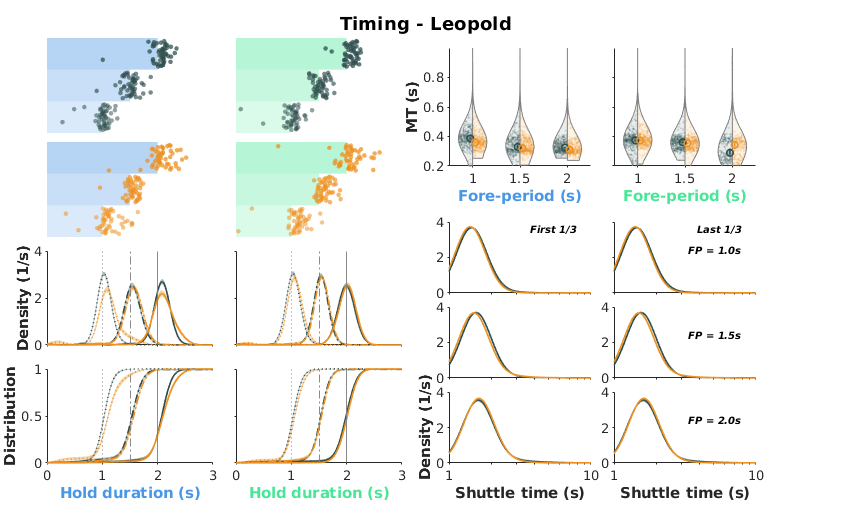

fig_total = figure(34); clf(fig_total);
set(fig_total, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 18 11], 'Color', 'w', 'toolbar', 'none');
set_fig_title(fig_total, sprintf("Timing - %s", Animal), 'FontSize', 11);

% show trials
DrawTrials(fig_total, [1 6 7.5 6.4], [3.5 2], HD);

% plot PDFs and CDFs
DrawDistr(fig_total, [1 1.2 7.5 4.5], [3.5 2], HDPDF, HDCDF);

% MT violin
ax_mt = DrawViolin(fig_total, [9.5 7.5 6.5 5.5], [3 2.5], FPs, MT, 1);
for i=1:numel(ax_mt)
    ax_mt{i}.YLim=[0.2 1];
end
ylabel(ax_mt{1}, "MT (s)", 'FontWeight', 'bold');

% ST
DrawShuttle(fig_total, [9.5 1.2 6.5 4.8], [3 1.5], FPs, LogSTPDF);

fig_name = sprintf("Test_Timing_Chemo_%s", Animal);
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_total, fig_path+".jpg", 'Resolution', 600);
exportgraphics(fig_total, fig_path+".pdf", 'ContentType', 'vector');

function ax = DrawTrials(fig, pos, ax_sz, data)
%% Show trials
Ports = ["L", "R"];
Labels = ["Control", "Chemo"];
Colors = ["Control", "Treat"];
sep_w = ( pos(3) - 2*ax_sz(1) ) / 1;
sep_h = ( pos(4) - 3*ax_sz(2) ) / 2;
dist_w = sep_w + ax_sz(1);
dist_h = sep_h + ax_sz(2);

ax = cell(2,2);
for p = 1:2
    for l = 1:2
        x_now = pos(1) + dist_w * (p-1);
        y_now = pos(2) + dist_h * (2-l);

        ax{l,p} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
            'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
        plot_trials(ax{l,p}, data.(Labels(l))(:,1), 'FP', [1 1.5 2], ...
            'FaceColor', GPSColor.("Port"+Ports(p)), 'MarkerColor', GPSColor.(Colors(l)), 'MarkerSize', 8);
        set(ax{l,p}, 'XLim', [0 3], 'XColor', 'none', 'YColor', 'none');
    end
end

drawnow();
end % DrawTrials

%%
function ax = DrawDistr(fig, pos, ax_sz, data_pdf, data_cdf)
%% Plot pdf and cdf
Ports = ["L", "R"];
sep_w = ( pos(3) - 2*ax_sz(1) ) / 1;
sep_h = ( pos(4) - 2*ax_sz(2) ) / 1;
dist_w = sep_w + ax_sz(1);
dist_h = sep_h + ax_sz(2);

ax = cell(2,2);
ymax = max(max(cellfun(@(x1, x2) max([x1.ci(2,:) x2.ci(2,:)]), data_pdf.Control, data_pdf.Chemo)));
ylim = ceil(ymax);

for p = 1:2
    % pdf
    x_now = pos(1) + dist_w * (p-1);
    y_now = pos(2) + dist_h * 1;
    ax{1,p} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
        'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
    plot_distr(ax{1,p}, data_pdf.Control(:,p), 'FP', [1 1.5 2], ...
        'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
    plot_distr(ax{1,p}, data_pdf.Chemo(:,p), 'FP', [1 1.5 2], ...
        'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
    set(ax{1,p}, 'XTickLabel', '', 'XLim', [0 3], 'YLim', [0 ylim]);
    if p==1
        ylabel(ax{1,p}, "Density (1/s)", 'FontWeight', 'bold');
    else
        set(ax{1,p}, 'YTickLabel', '');
    end

    % cdf
    x_now = pos(1) + dist_w * (p-1);
    y_now = pos(2) + dist_h * 0;
    ax{2,p} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
        'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
    plot_distr(ax{2,p}, data_cdf.Control(:,p), 'FP', [1 1.5 2], ...
        'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
    plot_distr(ax{2,p}, data_cdf.Chemo(:,p), 'FP', [1 1.5 2], ...
        'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', [":", "-.", "-"]);
    xlabel(ax{2,p}, "Hold duration (s)", 'FontWeight', 'bold', 'Color', GPSColor.("Port"+Ports(p)));
    if p==1
        ylabel(ax{2,p}, "Distribution", 'FontWeight', 'bold');
    else
        set(ax{2,p}, 'YTickLabel', '');
    end
    set(ax{2,p}, 'XLim', [0 3]);
end

drawnow();
end % DrawDistr

%%
function ax = DrawViolin(fig, pos, ax_sz, FPs, data, scale)
%% Plot violin comparations
Ports = ["L", "R"];
sep_w = ( pos(3) - 2*ax_sz(1) ) / 1;
dist_w = sep_w + ax_sz(1);

ax = cell(1,2);
for p = 1:2
    x_now = pos(1) + dist_w * (p-1);
    y_now = pos(2);

    ax{p} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
        'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');

    rt_1 = data.Control(:,p);
    rt_2 = data.Chemo(:,p);

    plot_violin_compare(ax{p}, rt_1, rt_2, .1, ...
        'cate_name', string(FPs), 'Color', {GPSColor.Control, GPSColor.Treat}, 'Scale', scale, 'Text', true);

    if p==2
        set(ax{p}, 'YTickLabel', '');
    end
    xlabel(ax{p}, "Fore-period (s)", 'FontWeight', 'bold', 'Color', GPSColor.("Port"+Ports(p)));

    set(ax{p}, 'XLim', [.5 3.5]);
end

end % DrawViolin

%%
function ax = DrawShuttle(fig, pos, ax_sz, FPs, data)
%% Plot shuttle time (first and last 1/3 trials)
sep_w = ( pos(3) - 2*ax_sz(1) ) / 1;
sep_h = ( pos(4) - 3*ax_sz(2) ) / 1;
dist_w = sep_w + ax_sz(1);
dist_h = sep_h + ax_sz(2);

st_pd_max = max(max(cellfun(@(x1, x2) max([x1.ci(2,:) x2.ci(2,:)]), data.Control, data.Chemo)));
st_pd_ylim = ceil(st_pd_max);

ax = cell(3,2);
for fp = 1:3
for p = 1:2
    x_now = pos(1) + dist_w * (p-1);
    y_now = pos(2) + dist_h * (3-fp);

    ax{fp,p} = axes(fig, "Units", "centimeters", "Position", [x_now y_now ax_sz], ...
        'NextPlot', 'add', 'FontSize', 8, 'TickDir', 'out');
    switch p
        case 1
            s = 1;
        case 2
            s = 3;
    end
    plot_distr(ax{fp,p}, data.Control(fp,s), ...
        'Color', GPSColor.Control, 'LineWidth', 1, 'LineStyle', "-");
    plot_distr(ax{fp,p}, data.Chemo(fp,s), ...
        'Color', GPSColor.Treat, 'LineWidth', 1, 'LineStyle', "-");

    set(ax{fp,p}, 'YLim', [0 st_pd_ylim], 'XLim', [0 1], ...
        'XTick', log10(1:10), 'XTickLabel', ["1" repmat("", 1, 8) "10"], 'XTickLabelRotation', 0);

    if fp==3
        xlabel(ax{fp,p}, "Shuttle time (s)", 'FontWeight', 'bold');
    else
        set(ax{fp,p}, 'XTickLabel', '');
    end
    if p==1
        if fp==1
            text(ax{fp,p}, .9, .9*st_pd_ylim, '\it{First 1/3}', 'Fontweight', 'bold', 'FontSize', 6, 'HorizontalAlignment', 'right');
        elseif fp==3
            ylabel(ax{fp,p}, "Density (1/s)", 'FontWeight', 'bold');
        end
    else
        text(ax{fp,p}, .9, .6*st_pd_ylim, sprintf('\\it{FP = %.1fs}', FPs(fp)), 'Fontweight', 'bold', 'FontSize', 6, 'HorizontalAlignment', 'right');
        if fp==1
            text(ax{fp,p}, .9, .9*st_pd_ylim, '\it{Last 1/3}', 'Fontweight', 'bold', 'FontSize', 6, 'HorizontalAlignment', 'right');
            set(ax{fp,p}, 'YTickLabel', '');
        end
    end
end
end
drawnow();
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function plot_trials(ax, data, varargin)

defaultColor = [0 0 0];
defaultSize = 18;
defaultNumShow = 50;
defaultFP = zeros(1, length(data));

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'data', @iscell);
addOptional(p,'n_show', defaultNumShow, @isnumeric);
addParameter(p,'FP', defaultFP, @(x) (isvector(x) && length(x)==length(data)));
addParameter(p,'FaceColor', defaultColor);
addParameter(p,'MarkerColor', defaultColor);
addParameter(p,'MarkerSize', defaultSize);

parse(p, ax, data, varargin{:});

ax = p.Results.ax;
data = p.Results.data;
n_show = p.Results.n_show;
FP = p.Results.FP;
FaceColor = p.Results.FaceColor;
MarkerColor = p.Results.MarkerColor;
MarkerSize = p.Results.MarkerSize;

%
n_show = min([n_show min(cellfun(@(x) length(x), data))]);

for i=1:length(data)
    if FP(i)~=0
        fill(ax, [0 FP(i) FP(i) 0], [0 0 1 1]+i-1, 'r', ...
            'FaceColor', FaceColor, 'FaceAlpha', .4*FP(i)/max(FP), 'EdgeColor', 'none');
    end
    id_show = randperm(length(data{i}), n_show);
    scatter(ax, data{i}(id_show), linspace(.1, .9, n_show)+i-1, MarkerSize, "filled", ...
        "MarkerEdgeColor", "none", "MarkerFaceColor", MarkerColor, "MarkerFaceAlpha", .75*sqrt(FP(i)/max(FP)));
end

% set(ax, 'XColor', 'none', 'YColor', 'none');
end

%%
function plot_distr(ax, data, varargin)

defaultColor = [0 0 0];
defaultLw = repmat(1.2, 1, length(data));
defaultLs = repmat("-", 1, length(data));
defaultFP = zeros(1, length(data));

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'data', @iscell);
addParameter(p,'FP', defaultFP, @(x) (isvector(x) && length(x)==length(data)));
addParameter(p,'Color', defaultColor);
addParameter(p,'LineWidth', defaultLw, @isvector);
addParameter(p,'LineStyle', defaultLs, @isvector);

parse(p, ax, data, varargin{:});

ax = p.Results.ax;
data = p.Results.data;
FP = p.Results.FP;
Color = p.Results.Color;
LineWidth = p.Results.LineWidth;
LineStyle = p.Results.LineStyle;

if length(LineWidth)==1
    LineWidth = repmat(LineWidth, 1, length(data));
elseif length(LineWidth)~=length(data)
    error("Unmatched length between lw and data");
end
if length(LineStyle)==1
    LineStyle = repmat(LineStyle, 1, length(data));
elseif length(LineStyle)~=length(data)
    error("Unmatched length between ls and data");
end
%

for i=1:length(data)
    if FP(i)~=0
        xline(ax, FP(i), 'LineStyle', LineStyle(i), 'Color', [.5 .5 .5]);
    end
    if ~isempty(data{i}.ci)
        fill(ax, [data{i}.x flip(data{i}.x)], [data{i}.ci(1,:) flip(data{i}.ci(2,:))], 'r', ...
            'FaceColor', Color, 'FaceAlpha', .4, 'EdgeColor', 'none');
    end
    plot(ax, data{i}.x, data{i}.f, 'Color', Color, 'LineWidth', LineWidth(i), 'LineStyle', LineStyle(i));
end

% set(ax, 'XColor', 'none', 'YColor', 'none');
end

%%
function plot_violin_compare(ax, datain_1, datain_2, band_width, varargin)

defaultCate = string(1:length(datain_1));
defaultColor = repmat({[0 0 0]}, 1, 2);
defaultScale = 1;

p = inputParser;
addRequired(p,'ax', @ishandle);
addRequired(p,'datain_1', @iscell);
addRequired(p,'datain_2', @iscell);
addRequired(p,'band_width', @isnumeric);
addParameter(p,'cate_name', defaultCate);
addParameter(p,'Color', defaultColor);
addParameter(p,'Scale', defaultScale);
addParameter(p,'Text', false);

parse(p, ax, datain_1, datain_2, band_width, varargin{:});

ax = p.Results.ax;
datain_1 = p.Results.datain_1;
datain_2 = p.Results.datain_2;
band_width = p.Results.band_width;
cate_name = p.Results.cate_name;
Color = p.Results.Color;
Scale = p.Results.Scale;
Text = p.Results.Text;

n_data_1 = max(cellfun(@length, datain_1));
n_data_2 = max(cellfun(@length, datain_2));
n_data = max([n_data_1 n_data_2]);

if length(n_data_1)~=length(n_data_2)
    error("input data dont match");
else
    n_cate = length(datain_1);
end

%
data_1 = nan(n_data, n_cate);
data_2 = nan(n_data, n_cate);

for i = 1:n_cate
    data_1(1:length(datain_1{i}), i) = Scale*datain_1{i};
    data_2(1:length(datain_2{i}), i) = Scale*datain_2{i};
end

data_med_ci_1 = bootci(1000, @(x) median(x, 'omitnan'), data_1);
data_med_ci_2 = bootci(1000, @(x) median(x, 'omitnan'), data_2);

data_med_1 = median(data_1, 'omitnan');
data_med_2 = median(data_2, 'omitnan');

%
axes(ax);
v = violinplot({data_2, data_1}, cate_name, ...
    'ViolinColor', Color([2 1]), 'ViolinAlpha', {.1, .1}, ...
    'BandWidth', Scale*band_width, 'MarkerSize', 2, ...
    'ShowMedian', false, 'ShowWhiskers', false, 'ShowBox', false);
xlim(ax, [.5 n_cate+.5]);

for i = 1:n_cate
    v(i).ScatterPlot.MarkerFaceAlpha = .2;
    v(i).ScatterPlot2.MarkerFaceAlpha = .2;

    scatter(ax, i-.05, data_med_1(i), 16, Color{1}, "filled", ...
        'LineWidth', 1, 'MarkerEdgeColor', 'flat', ...
        'MarkerFaceColor', 'none');
    scatter(ax, i+.05, data_med_2(i), 16, Color{2}, "filled", ...
        'LineWidth', 1, 'MarkerEdgeColor', 'flat', ...
        'MarkerFaceColor', 'none');
    plot(ax, [i-.05 i-.05], data_med_ci_1(:,i), 'Color', Color{1}, 'LineWidth', 1);
    plot(ax, [i+.05 i+.05], data_med_ci_2(:,i), 'Color', Color{2}, 'LineWidth', 1);

    if Text
        text(ax, i-.05, 350, sprintf('%.0f', data_med_1(i)), 'FontSize', 5, 'HorizontalAlignment', 'right');
        text(ax, i+.05, 350, sprintf('%.0f', data_med_2(i)), 'FontSize', 5, 'HorizontalAlignment', 'left');
    end
    set(ax, 'Box', 'off');
end

end


